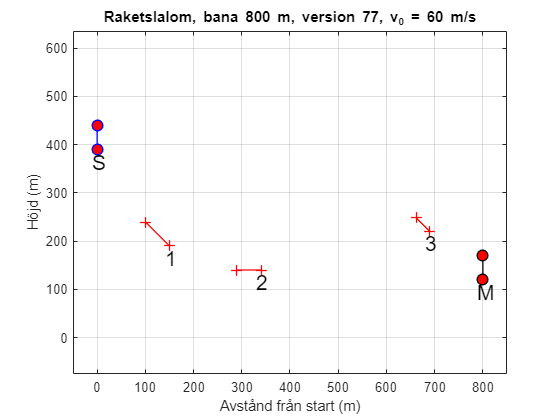

clear
load bana800-77.mat
plotTrack(portx, porty, ver, v1)

c = 0.25; % kg/m
g = 9.82; % m/s^2
km = 2000; % m/s
alpha = 0;
tspan = [0,800];
xybv = [0;400];
n = 100;
[t,y] = minRK2(@mp3Funk, tspan, xybv, n)

Unable to perform assignment because the size of the left side is 1-by-101 and the size of the right side is 2-by-1.

Error in minRK2 (line 8)
y(1,:) =xy1;

plot(t, y)

hold on
clear
clf
x = linspace(1,800,800)
% 400 + −2,18x + 4,89×10^−03x^2 + −2,05×10^−06x^3 + −1,46×10^−09x^4
y = 400 - 2.18 * x + 4.89 * 10^-3 * x.^2 - 2.05 * 10^-6 * x.^3 - 1.46*10^-9 * x.^4
plot(x, y, '--r')
hold off
% deriv
% -2.18 + 0.00978 x - 6.15×10^-6 x.^2 - 5.84×10^-9 x.^3
yderiv = -2.18 + 0.00978 * x - 6.15 * 10^-6 * x.^2 - 5.84 * 10^-9 * x.^3
plot(x, yderiv, '--g')
hold on
